values =    [3840 2550 2050 1760 1590 1470 1360 1300 1220 1200 1160 1140 1110 1090 1060 1055 1050 1030 1020 1010]

values =         3840        2550        2050        1760        1590        1470        1360        1300        1220        1200        1160        1140        1110        1090        1060        1055        1050        1030        1020        1010


distances = [5    10   15   20   25   30   35   40   45   50   55   60   65   70   75   80   85   90   95   100 ]

distances =      5    10    15    20    25    30    35    40    45    50    55    60    65    70    75    80    85    90    95   100


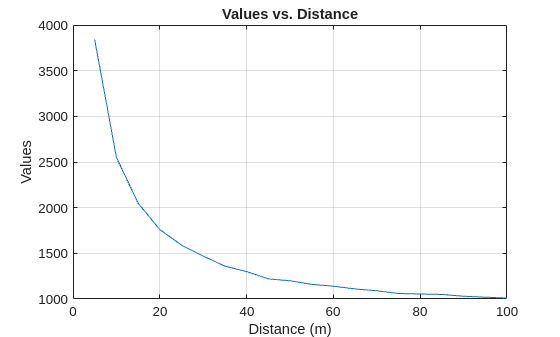


plot(distances,values)
hold on
xlabel('Distance (m)');
ylabel('Values');
title('Values vs. Distance');
grid on;
hold off


T = table(distances(:), values(:), 'VariableNames', {'Distance_m','Value'});
disp(T);

    Distance_m    Value
    __________    _____

         5        3840 
        10        2550 
        15        2050 
        20        1760 
        25        1590 
        30        1470 
        35        1360 
        40        1300 
        45        1220 
        50        1200 
        55        1160 
        60        1140 
        65        1110 
        70        1090 
        75        1060 
        80        1055 
        85        1050 
        90        1030 
        95        1020 
       100        1010 




% Calculate the average gradient
averageGradient = mean(gradients);
fprintf('Average Gradient: %.2f Value/m\n', averageGradient);
% compute gradient (difference in value divided by difference in distance) between neighboring points
dx = diff(distances);
dy = diff(values);
gradients = dy ./ dx;

% create table of gradients with corresponding mid-point distances or interval labels
midDistances = (distances(1:end-1) + distances(2:end)) / 2;
G = table(distances(1:end-1)', distances(2:end)', midDistances', gradients', ...
    'VariableNames', {'Distance_Start_m','Distance_End_m','Midpoint_m','Gradient_ValuePerMeter'});
disp(G);

    Distance_Start_m    Distance_End_m    Midpoint_m    Gradient_ValuePerMeter
    ________________    ______________    __________    ______________________

            5                 10              7.5                -258         
           10                 15             12.5                -100         
           15                 20             17.5                 -58         
           20                 25             22.5                 -34         
           25                 30             27.5                 -24         
           30                 35             32.5                 -22         
           35                 40             37.5                 -12         
           40                 45             42.5                 -16         
           45                 50             47.5                  -4    